inputs

tol = 1e-4

tol = 1.0000e-04

func1 = @(lambda) 1e6.*exp(lambda) + ...
    (435e3./lambda).*(exp(lambda) - 1) - ...
    1564e3

func1 = function_handle with value:
    @(lambda)1e6.*exp(lambda)+(435e3./lambda).*(exp(lambda)-1)-1564e3



a = 0.001

a = 1.0000e-03

b = 0.125

b = 0.1250

p0 = 0.05

p0 = 0.0500

max_iter = 100

max_iter = 100

bisection

[root1, iter1, tab1] = bisection_method_function( ...
    a, b, tol, max_iter, func1 ...
)

root1 = 0.1010

iter1 = 11

tab1 = 11×7 table
    iter       a           b          p            f_a         f_b        f_p  
    ____    ________    _______    ________    ___________    ______    _______

      1        0.001      0.125       0.063    -1.2778e+05     32505     -49978
      2        0.063      0.125       0.094         -49978     32505    -9339.3
      3        0.094      0.125      0.1095        -9339.3     32505      11430
      4        0.094     0.1095     0.10175        -9339.3     11430     1007.4
      5        0.094    0.10175    0.097875        -9339.3    1007.4    -4175.4
      6     0.097875    0.10175    0.099812        -4175.4    1007.4    -1586.4
      7     0.099812    0.10175     0.10078        -1586.4    1007.4     -290.1
      8      0.10078   

newton

[root2, iter2, tab2] = newton_method_function( ...
    p0, tol, max_iter, func1 ...
)

root2 = 0.1010

iter2 = 3

tab2 = 3×6 table
    iter      p0          p        f_p0        df_p0          f_p    
    ____    _______    _______    _______    __________    __________

     1         0.05    0.10224     -66670    1.2762e+06        1668.1
     2      0.10224      0.101     1668.1    1.3406e+06       0.97837
     3        0.101      0.101    0.97837     1.339e+06    3.3667e-07

	Get insights using Copilot


fprintf(...
    "bisection; root = %f; iteration = %d\n" + ...
    "newton   ; root = %f; iteration = %d\n", ...
    root1, iter1, root2, iter2 ...
);

bisection; root = 0.100963; iteration = 11
newton   ; root = 0.100998; iteration = 3


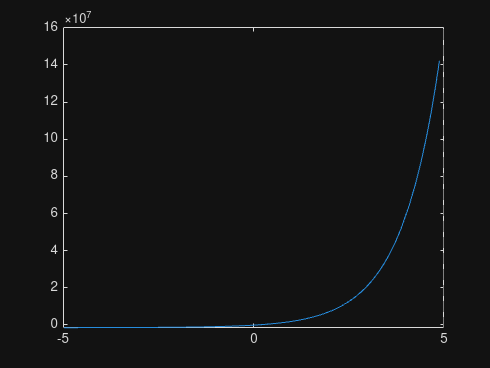

figure
fplot(func1)

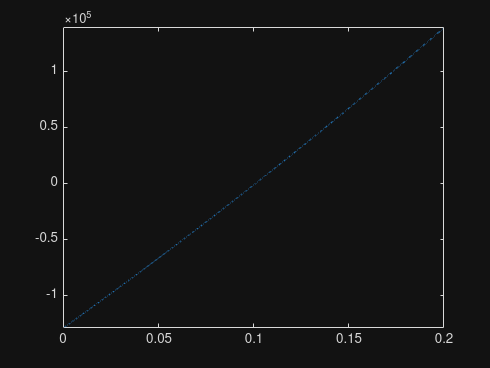

figure
fplot(func1, [0, 0.2])